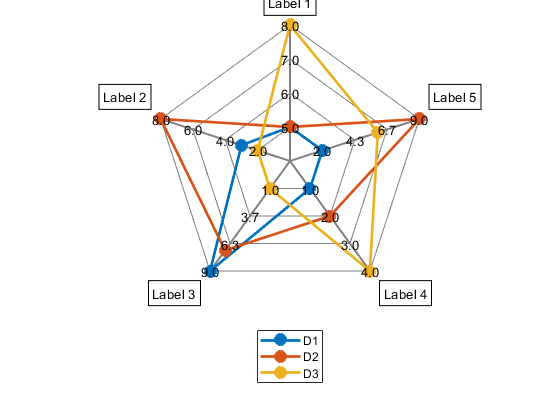

% Example 1: Minimal number of arguments. All non-specified, optional arguments are set to their default values. Axes labels and limits are automatically set.
D1 = [5 3 9 1 2];   % Initialize data points
D2 = [5 8 7 2 9];
D3 = [8 2 1 4 6];
P = [D1; D2; D3];

spider_plot(P);

legend('D1', 'D2', 'D3', 'Location', 'southoutside');

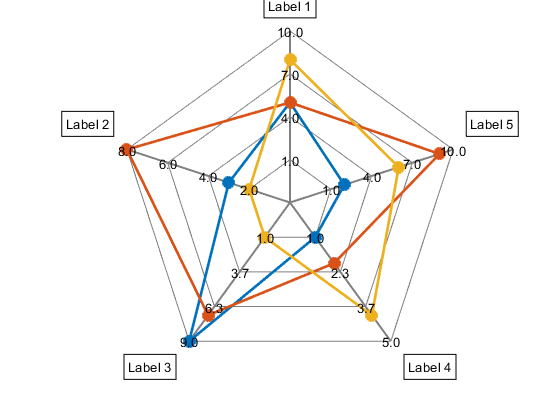

% Example 2: Manually setting the axes limits. All non-specified, optional arguments are set to their default values.
axes_limits = [1, 2, 1, 1, 1; 10, 8, 9, 5, 10]; % Axes limits [min axes limits; max axes limits]

spider_plot(P,...
    'AxesLimits', axes_limits);

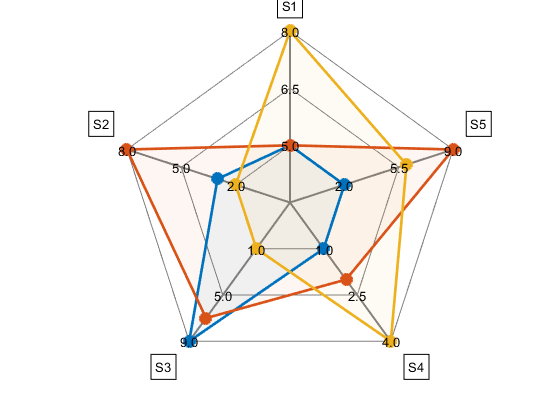

% Example 3: Set fill option on. The fill transparency can be adjusted.
axes_labels = {'S1', 'S2', 'S3', 'S4', 'S5'}; % Axes properties
axes_interval = 2;
fill_option = 'on';
fill_transparency = 0.05;

spider_plot(P,...
    'AxesLabels', axes_labels,...
    'AxesInterval', axes_interval,...
    'FillOption', fill_option,...
    'FillTransparency', fill_transparency);

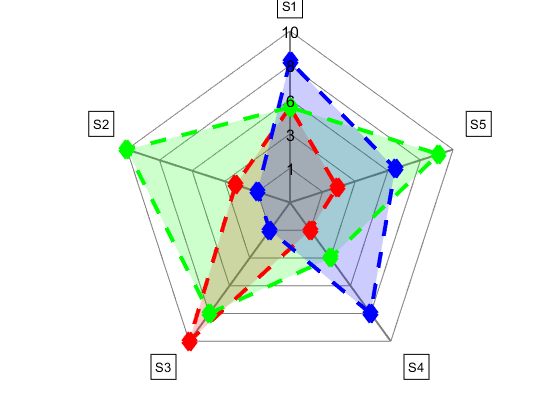

% Example 4: Maximum number of arguments.
axes_labels = {'S1', 'S2', 'S3', 'S4', 'S5'}; % Axes properties
axes_interval = 4;
axes_precision = 0;
axes_display = 'one';
axes_limits = [1, 2, 1, 1, 1; 10, 8, 9, 5, 10];
fill_option = 'on';
fill_transparency = 0.2;
colors = [1, 0, 0; 0, 1, 0; 0, 0, 1];
line_style = '--';
line_width = 3;
marker_type = 'd';
marker_size = 10;
axes_font_size = 12;
label_font_size = 10;

spider_plot(P,...
    'AxesLabels', axes_labels,...
    'AxesInterval', axes_interval,...
    'AxesPrecision', axes_precision,...
    'AxesDisplay', axes_display,...
    'AxesLimits', axes_limits,...
    'FillOption', fill_option,...
    'FillTransparency', fill_transparency,...
    'Color', colors,...
    'LineStyle', line_style,...
    'LineWidth', line_width,...
    'Marker', marker_type,...
    'MarkerSize', marker_size, ...
    'AxesFontSize', axes_font_size,...
    'LabelFontSize', label_font_size);

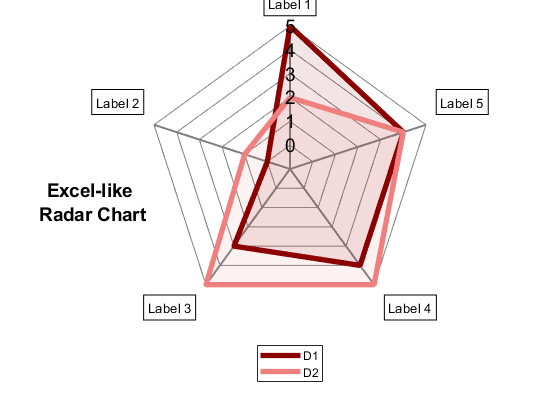

% Example 5: Excel-like radar charts.
D1 = [5, 0, 3, 4, 4]; % Initialize data
D2 = [2, 1, 5, 5, 4];
P = [D1; D2];

axes_interval = 5;% Axes properties
axes_precision = 0;
axes_display = 'one';
axes_limits = [0, 0, 0, 0, 0; 5, 5, 5, 5, 5];
fill_option = 'on';
fill_transparency = 0.1;
colors = [139, 0, 0; 240, 128, 128]/255;
line_width = 4;
marker_type = 'none';
axes_font_size = 14;
label_font_size = 10;

% Spider plot
spider_plot(P,...
    'AxesInterval', axes_interval,...
    'AxesPrecision', axes_precision,...
    'AxesDisplay', axes_display,...
    'AxesLimits', axes_limits,...
    'FillOption', fill_option,...
    'FillTransparency', fill_transparency,...
    'Color', colors,...
    'LineWidth', line_width,...
    'Marker', marker_type,...
    'AxesFontSize', axes_font_size,...
    'LabelFontSize', label_font_size);

title(sprintf('Excel-like\n Radar Chart'),...
    'Units', 'normalized',...
    'Position', [-0.2, 0.3, 0],...
    'FontSize', 14);
legend_str = {'D1', 'D2'};
legend(legend_str, 'Location', 'southoutside');